# Using Sensitivity-Information for Parameter-Estimation (PE) in the Case of Cabbage growth

*Note: This script requires the optimization toolbox & statistics and machine learning toolbox *

The sensitivitie information (see: [CanonicalSensitivities.mlx](matlab:open('./CanonicalSensitivities.mlx'))) generated by the FDstep contains directional derivatives for all coordinate directions of the parameters and starting values and can thus be used for optimization algorithms. Here we test this with a single shooting approach for a PE problem, modeling cabbage growth. 

The Cabbage Growth PE is described by:

- a switched ODE (first the Cabbage grows mainly vertically and later switches to horizontal growth)

- Measurements over time of an "observed" example (here, the measurements are taken by randomly perturbing the correct solution trajectory)

The Right-Hand-Side of the ODE is give by:

clear; initPaths(); type whiteCabbageRHS.m


function dy = whiteCabbageRHS(t, y, p)
   %RHS for growth of white cabbage model
   
   dy = zeros(3,1);
   
   dy(1) = p(2) * (p(1) + 1)/(p(1) + exp(p(4) * t)) * y(1) - p(3) * y(1);
   
   dy(2) = p(5) * (p(8) * y(1) - y(2));
   
   if  t <= p(9)
      dy(3) = 0;
   else
      dy(3) = p(6) * y(1) - p(7) * y(3);
   end

end


%% Solution ifdiff
initPaths();
integrator = @ode45;
odeoptionsrhs_test = odeset( 'AbsTol', 1e-14,'RelTol', 1e-12);
datahandle    = prepareDatahandleForIntegration('whiteCabbageRHS', 'integrator', func2str(integrator), 'options', odeoptionsrhs_test);

tspan         = [0 118];
initialvalues = [2.48252;0;0];
parameters_ODE = getParams_Cabbage();
sol = solveODE(datahandle, tspan, initialvalues, parameters_ODE);
%s = rng;

%% Precalculations for finite differences for sensitivities
dim_y = size(sol.y, 1);
dim_p = length(parameters_ODE);
FDstep = generateFDstep(dim_y, dim_p);

%% Generation of the measurements 
t = 0:118;
disturb = true;
sigma = 5;
%rng(s);
rand = randn(dim_y*length(t),1);
if disturb
   measurements = reshape(deval(sol, t), [], 1) + sigma.*rand;
else
   measurements = reshape(deval(sol, t), [], 1);
end

%% Generation of residual function
integrator_residual = @solveODE;
RHS = @whiteCabbageRHS;
method = 'VDE';
residual_function = generateResidualFunction(t, datahandle, sol, measurements, tspan, parameters_ODE, RHS, FDstep, integrator_residual, method);

%% Parameter estimation
options = optimoptions('lsqnonlin','SpecifyObjectiveGradient',true, 'Algorithm','levenberg-marquardt', 'Display', 'iter', 'DerivativeCheck', 'off', 'typicalX', [parameters_ODE;1;1;1]);%, 'TolX', 1e-14, 'TolFun', 1e-14);
parameters_init = [1.2*parameters_ODE; measurements(1:dim_y)];
tic;
[param_opt,resnorm,residual,exitflag,output,lambda,jacobian] = lsqnonlin(residual_function, parameters_init, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           1      8.99212e+07         1.3e+10         0.01
     1           2      7.07718e+06        1.16e+09        0.001        116.107
     2           3      2.39818e+06        1.24e+08       0.0001         35.534
     3           4       1.5589e+06        6.16e+08        1e-05        42.0168
     4           5          41086.6        1.09e+07        1e-06        66.9422
     5           6          9776.32           2e+06        1e-07        967.121
     6           8           9489.2        9.99e+05        1e-06        972.685
     7           9          9487.04        8.54e+05        1e-07        855.393
     8          11          9485.31        6.77e+05        1e-06        744.402
     9          12          9484.06        5.24e+05        1e-07        641.923
    10          14          9483.17        3.97e+05  

toc;

Elapsed time is 69.169882 seconds.


percent = (param_opt*100./[getParams_Cabbage();2.48252;0;0])-100

percent =    -1.9024
   -0.4598
   -1.1642
   -0.3328
    4.6611
    0.7147
    0.8203
    0.1918
   -0.0138
    1.2897


param_opt

param_opt = 1.0e+04 *

    3.3814
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0061
    0.0003


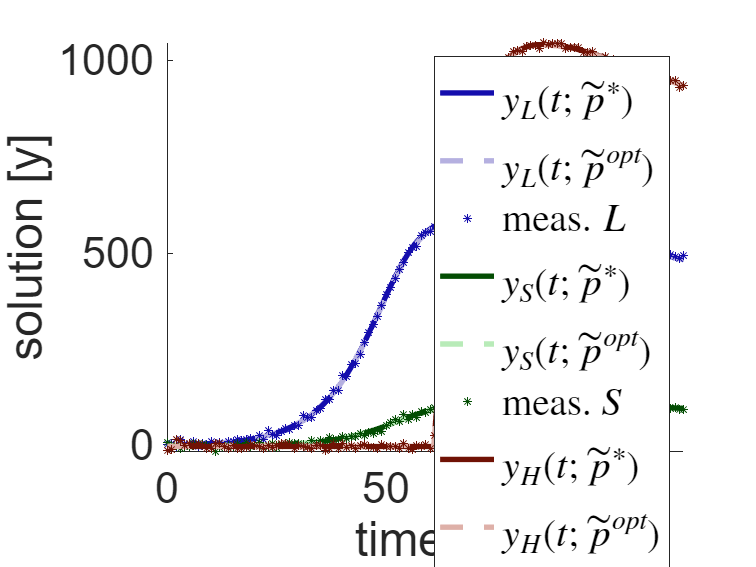


%% Joint confidence intervals
CI = nlparci(param_opt,residual,'jacobian',jacobian);


%% Solution with estimated parameters
initialvalues_opt = param_opt(10:12);
parameters_ODE_opt = param_opt(1:9);
sol_opt = solveODE(datahandle, tspan, initialvalues_opt, parameters_ODE_opt);

%% Plot of real solution and of solution with estimated parameters
measurements_plot = reshape(measurements, 3, []);
figure(2)
plot(sol.x, sol.y(1,:),'LineWidth', 3, 'color', [0.08,0.05,0.68]);
hold on
plot(sol_opt.x, sol_opt.y(1,:), '--', 'LineWidth', 3, 'color', [0.71,0.69,0.88]);
plot(t, measurements_plot(1,:), '*', 'MarkerSize', 5, 'color', [0.08,0.05,0.68]);
plot(sol.x, sol.y(2,:),'LineWidth', 3, 'color', [0.01,0.30,0.01]);
plot(sol_opt.x, sol_opt.y(2,:), '--', 'LineWidth', 3, 'color', [0.72,0.92,0.72]);
plot(t, measurements_plot(2,:), '*', 'MarkerSize', 5, 'color', [0.01,0.30,0.01]);
plot(sol.x, sol.y(3,:),'LineWidth', 3, 'color', [0.44,0.07,0.02]);
plot(sol_opt.x, sol_opt.y(3,:), '--', 'LineWidth', 3, 'color', [0.87,0.69,0.66]);
plot(t, measurements_plot(3,:), '*', 'MarkerSize', 5, 'color', [0.44,0.07,0.02]);
xlabel('time [t]')
ylabel('solution [y]')
set(gca, 'FontSize', 24);
set(gca, 'Box', 'off');
hold off 
legend({'$y_L(t;\tilde{p}^{\ast})$', '$y_L(t;\tilde{p}^{opt})$', 'meas. $L$', '$y_S(t;\tilde{p}^{\ast})$', '$y_S(t;\tilde{p}^{opt})$', 'meas. $S$', '$y_H(t;\tilde{p}^{\ast})$', '$y_H(t;\tilde{p}^{opt})$', 'meas. $H$'}, 'Interpreter', 'LaTeX');